Here we continue the analysis of eddy transport, looking at several details including the nature of the zonal jet. 

%------------------------------------------------------------------------
%Load the data
%This is when your NetCDF file is kept
ncdir='/Users/lilly/Desktop/Dropbox/NetCDF/';
filename='BetaEddyOne.nc';

%loading in data
lato=ncread([ncdir filename],'latitude');
f0=abs(corfreq(lato))/3600; %rad/s

x=ncread([ncdir filename],'x')/1000;%store distances in km
y=ncread([ncdir filename],'y')/1000;%store distances in km
ssh=squeeze(ncread([ncdir filename],'ssh'))*100;%store ssh in cm
u=squeeze(ncread([ncdir filename],'u'))*100;%store velocities in cm/s
v=squeeze(ncread([ncdir filename],'v'))*100;%store velocities in cm/s

%vorticity, shear strain, and normal strain, nondimensionalized by f0
zeta=squeeze(ncread([ncdir filename],'zeta'))/f0;
sigma=squeeze(ncread([ncdir filename],'sigma'))/f0;
nu=squeeze(ncread([ncdir filename],'nu'))/f0;
 
drifter_x=ncread([ncdir filename],'drifter_x')'/1000;%in km
drifter_y=ncread([ncdir filename],'drifter_y')'/1000;%in km 
drifter_u=ncread([ncdir filename],'drifter_u')'*100;%in cm/s
drifter_v=ncread([ncdir filename],'drifter_v')'*100;%in cm/s
%drifter_zeta=ncread([ncdir filename],'drifter_zeta')'./f0;
drifter_t=vrep([1:size(drifter_x,1)]',size(drifter_x,2),2);%time for drifters
%------------------------------------------------------------------------
%Compute eddy center location and largest instanteous closed streamline
[xo,yo]=eddyCenterFromField(x,y,ssh,0.9,method="timesMax");
[xp,yp,sshEddy]=fieldInEddyFrame(x,y,xo,yo,300,ssh);

uo=vdiff(xo,1,'endpoint')*100*1000/(24*3600);%km/day to cm/s
vo=vdiff(yo,1,'endpoint')*100*1000/(24*3600);%km/day to cm/s

[psip,psi,psif] = eddyFrameStreamFunction(1000*xp,1000*yp,sshEddy/100,uo/100,vo/100,f0);

tic;
[xpc,ypc,levels,index]=largestClosedStreamline(xp,yp,psip/1000,0.25);
toc
xc=celladd(xpc,xo);%put these contours back in the Earth frame
yc=celladd(ypc,yo);

%finally, mark particles as inside or outside trapping region 
isTrapped=isParticleEnclosed(drifter_x,drifter_y,xc,yc);
%------------------------------------------------------------------------

Elapsed time is 17.892371 seconds.


Now let's take a closer look at the jet feature. 

%u_std =  reshape(vstd(drifter_u,1),length(x),length(y))';
%v_std =  reshape(vstd(drifter_v,1),length(x),length(y))';
% [zp,zn]=anatrans(drifter_x+1i*drifter_y,conj(drifter_x+1i*drifter_y),1);
% p_std =  abs(reshape(vstd(zp,1),length(x),length(y))');
% n_std =  abs(reshape(vstd(zn,1),length(x),length(y))');
% 
% %what I really want is the eigenvalue of the velocity covariance matrix
% Suv = reshape(vmean((drifter_u-mean(drifter_u,1)).*(drifter_v-mean(drifter_v,1)),1),length(x),length(y))';
% [d1,d2,th,nu]=specdiag(u_std.^2,v_std.^2,Suv);
% 
% S_pp = reshape(vmean((zp-mean(zp,1)).*conj(zp-mean(zp,1)),1),length(x),length(y))';
% S_nn = reshape(vmean((zn-mean(zn,1)).*conj(zn-mean(zn,1)),1),length(x),length(y))';
% S_pn = reshape(vmean((zp-mean(zp,1)).*conj(zn-mean(zn,1)),1),length(x),length(y))';
% 
% [d1,d2,th,nu]=specdiag(S_pp,S_nn,S_pn);
%jpcolor(v_std.^2*100*100-u_std.^2*100*100)
%clim([-6 6 ])
%colormap(crameri('broc'))

ud=reshape(drifter_u,[size(drifter_u,1) length(x) length(y)]);
ud=permute(ud,[3 2 1]);

vd=reshape(drifter_v,[size(drifter_v,1) length(x) length(y)]);
vd=permute(vd,[3 2 1]);

iT=reshape(isTrapped,[size(isTrapped,1) length(x) length(y)]);
iT=permute(iT,[3 2 1]);

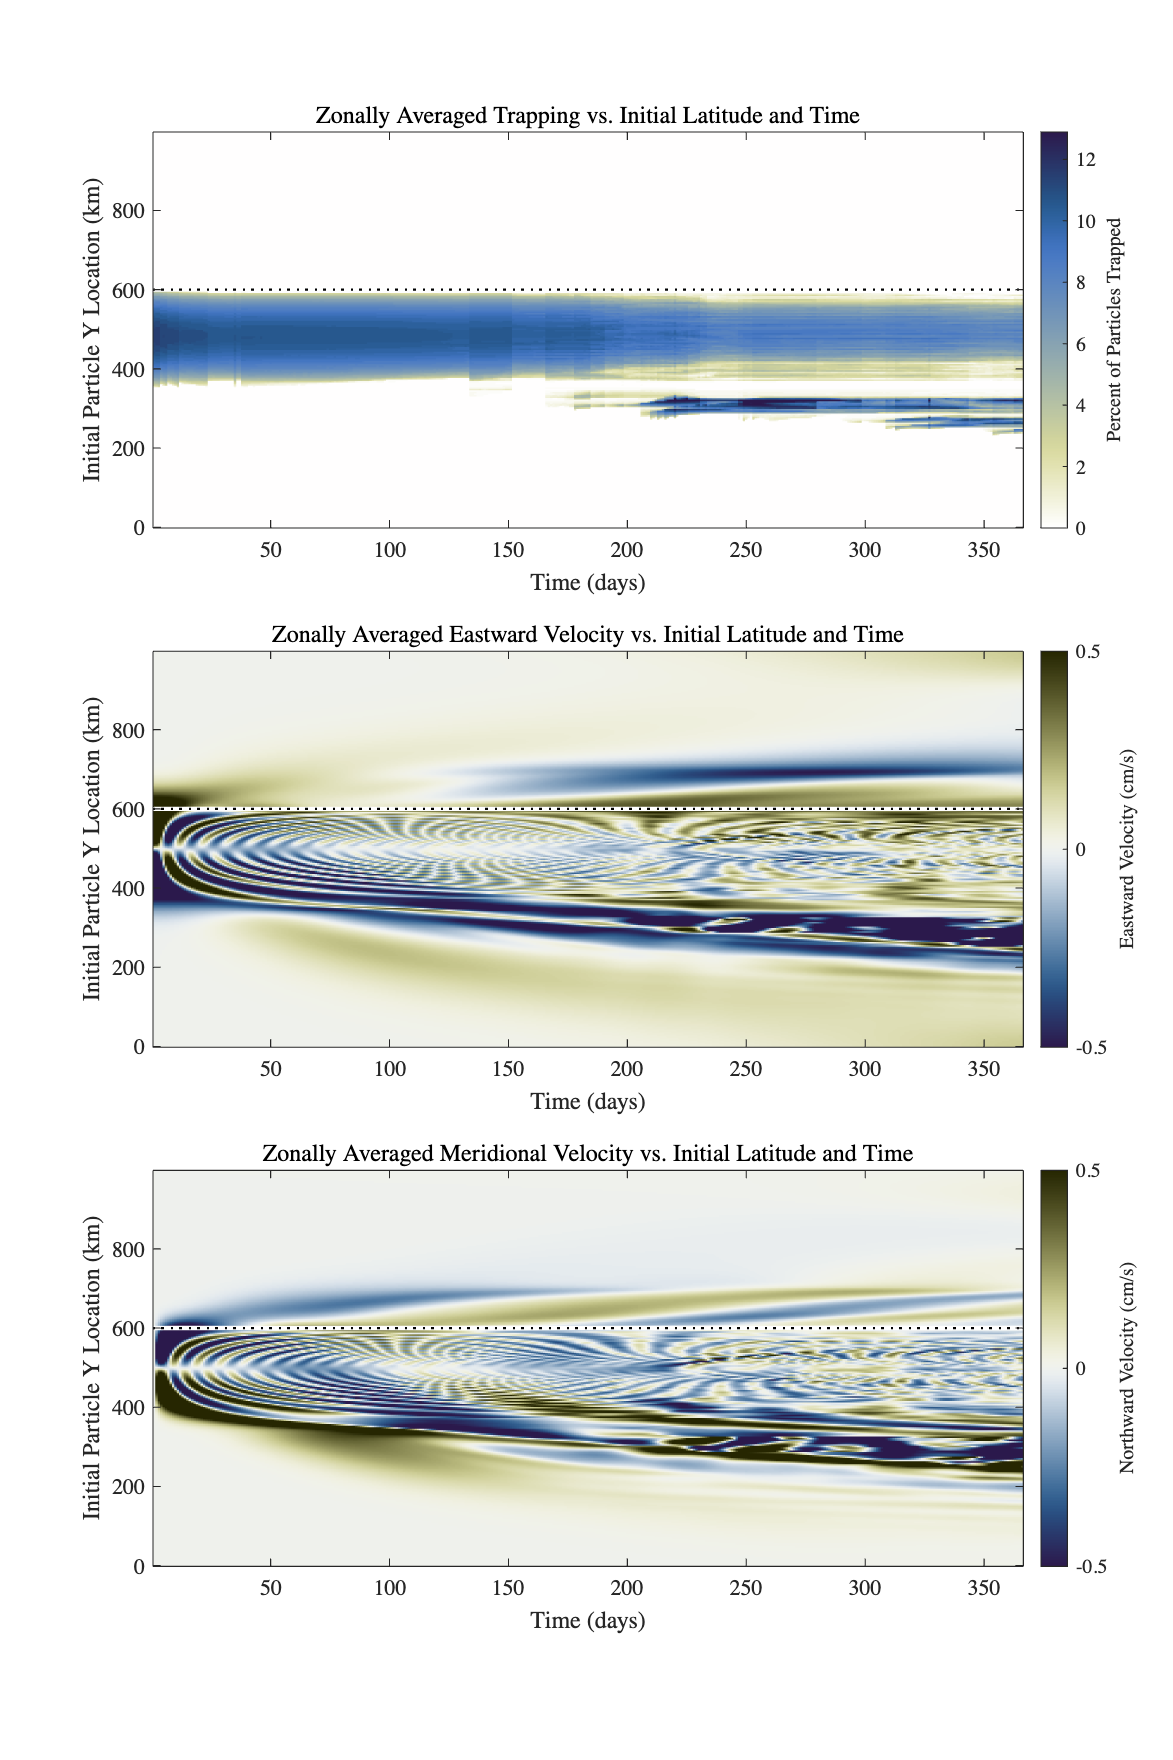

hf = figure();
hf.Position(3:4) = [1200,1800];
colormap(crameri('broc'))

tiledlayout(3,1)

ha=nexttile;
jpcolor(1:size(iT,3),y,mean(100*iT,2)),axis tight
hlines(600,'2w'),hlines(600,'k:')
hc=colorbar('location','EastOutside');
hc.Label.String = "Percent of Particles Trapped";
title("Zonally Averaged Trapping vs. Initial Latitude and Time")
xlabel('Time (days)')
ylabel('Initial Particle Y Location (km)')
colormap(ha,flipud(crameri('davos')))

nexttile
jpcolor(1:size(iT,3),y,mean(ud,2)),axis tight
hlines(600,'2w'),hlines(600,'k:')
hc=colorbar('location','EastOutside');
hc.Label.String = "Eastward Velocity (cm/s)";
title("Zonally Averaged Eastward Velocity vs. Initial Latitude and Time")
xlabel('Time (days)')
ylabel('Initial Particle Y Location (km)'),clim([-1 1]/2)

nexttile
jpcolor(1:size(iT,3),y,mean(vd,2)),axis tight
hlines(600,'2w'),hlines(600,'k:')
hc=colorbar('location','EastOutside');
hc.Label.String = "Northward Velocity (cm/s)";
title("Zonally Averaged Meridional Velocity vs. Initial Latitude and Time")
xlabel('Time (days)')
ylabel('Initial Particle Y Location (km)'),clim([-1 1]/2)

The north-south asymmetry of the jet evoluiton is clear.  Note (i) there is no entrainment from north of the initial vortex location and (ii) the zonal jet to the north of the eddy appears to develop into a persistent feature, unlike the meridional currents associated with the Rossby wave wake. 

Let's look at some more characterizations of the eddy to try to understand this jet feature better. 

zu=anatrans(u,3);
zv=anatrans(v,3);

[au,omu,nuu]=instmom(1,zu,3);
[av,omv,nuv]=instmom(1,zv,3);

[kappa,lambda,theta,phi]=ellparams(zu,zv,3);
[a,b,c,upsilon]=ellband(1,kappa,lambda,theta,phi,3);  
ombar=frac(mean(au.^2.*omu+av.^2.*omv,3),mean(au.^2+av.^2,3));

%% Rotary decomposition is less interesting
% [zp,zn]=anatrans(u+1i*v,u-1i*v,3);
% [ap,omp]=instmom(1,zp,3);
% [an,omn]=instmom(1,zn,3);
% figure,jpcolor(vmean(ap.^2,3)-vmean(an.^2,3))

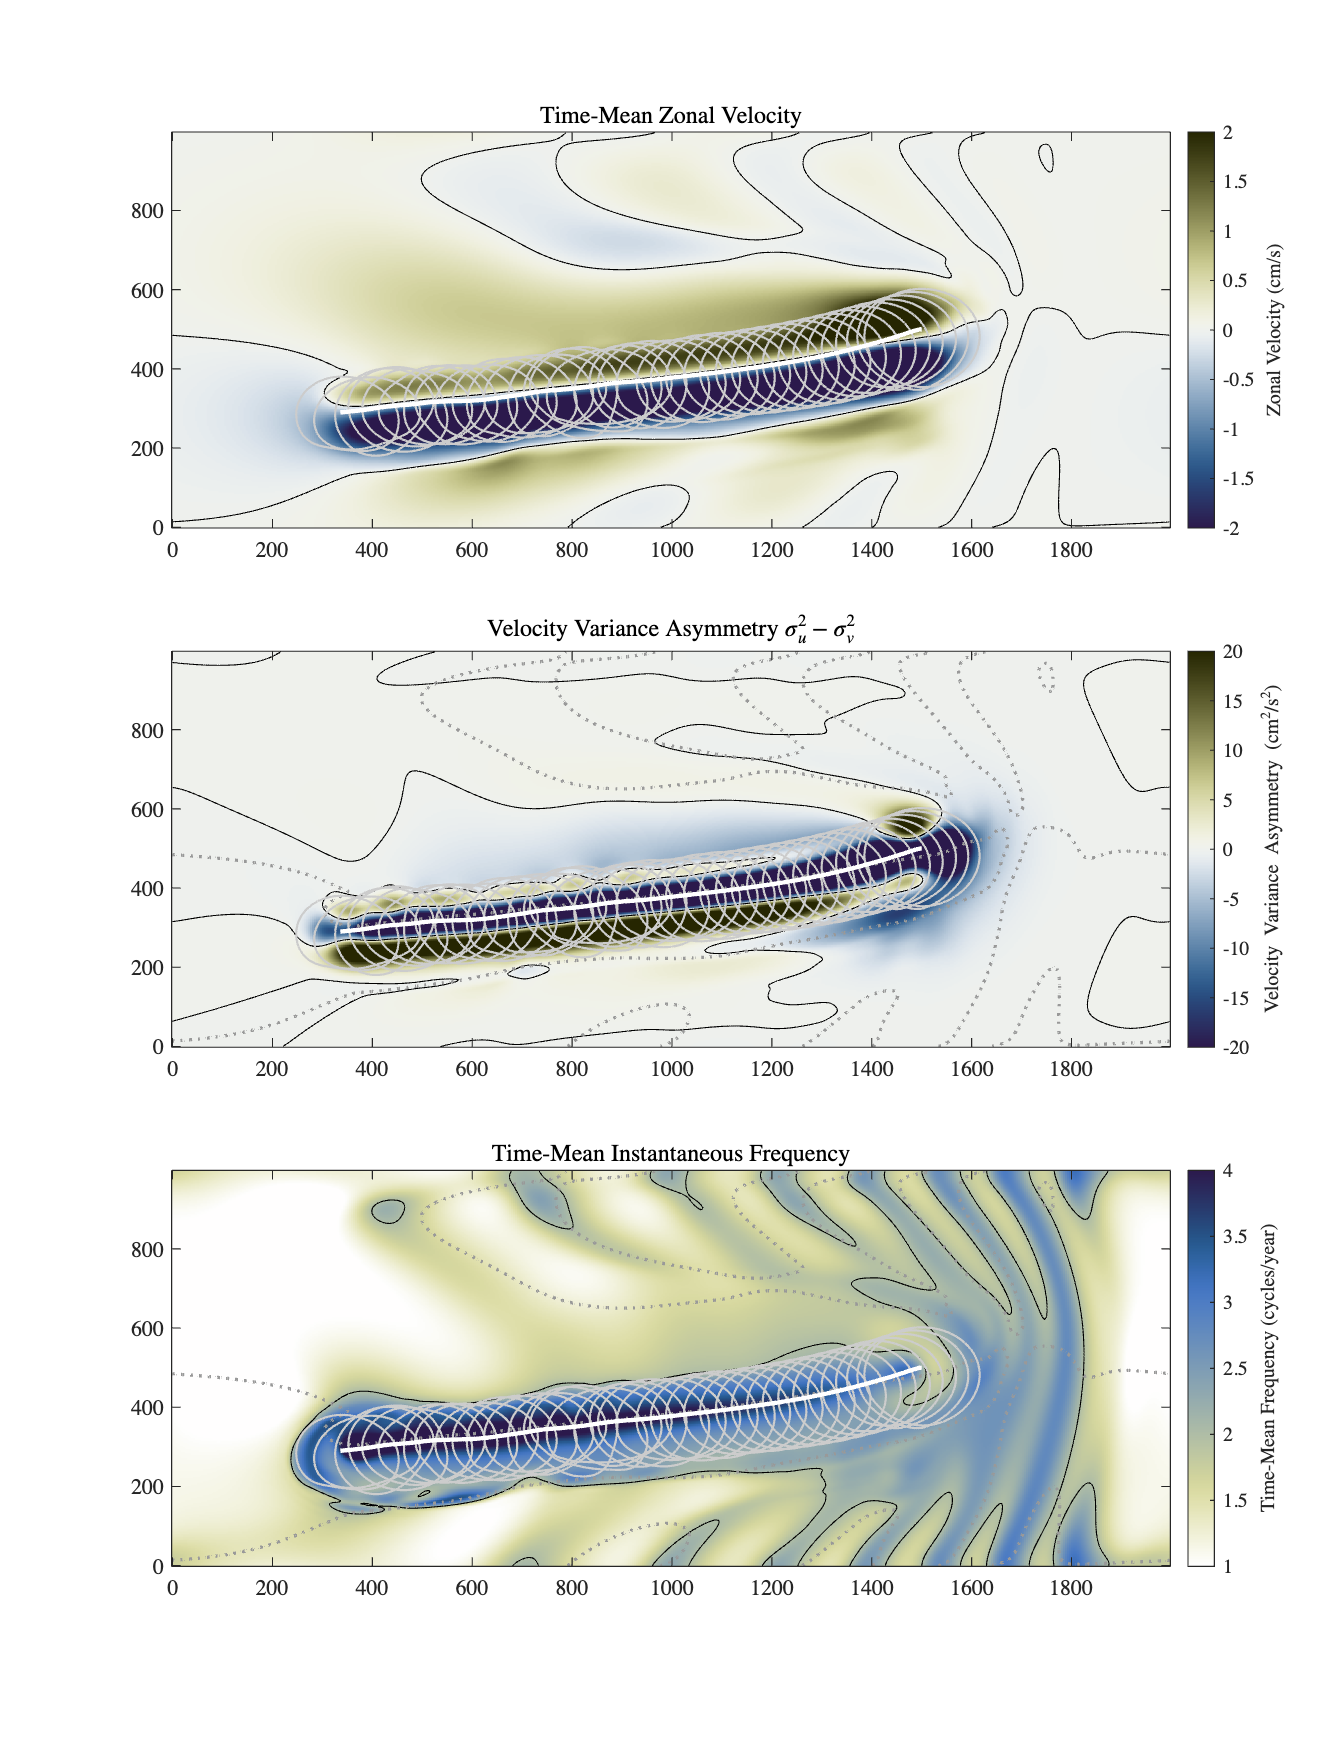

hf = figure();
hf.Position(3:4) = [1200,1600];
colormap(crameri('broc'))

tiledlayout(3,1)

nexttile;
jpcolor(x,y,vmean(u,3)'),axis tight,hold on
contour(x,y,vmean(u,3)',[0 0],'k')
cellplot(xc(1:10:end),yc(1:10:end),'C')
plot(xo,yo,'w',linewidth=2)
hc=colorbar('location','EastOutside');
hc.Label.String = "Zonal Velocity (cm/s)";
title("Time-Mean Zonal Velocity")
clim([-2 2])

nexttile;
jpcolor(x,y,(vstd(u,3).^2-vstd(v,3).^2)'),axis tight,hold on
contour(x,y,(vstd(u,3).^2-vstd(v,3).^2)',[0 0],'k')
contour(x,y,vmean(u,3)',[0 0],color=[1 1 1]*0.6,linewidth=1.5,linestyle=':')
cellplot(xc(1:10:end),yc(1:10:end),'C')
plot(xo,yo,'w',linewidth=2)
%hlines(600,'2w'),hlines(600,'k:'),
hc=colorbar('location','EastOutside');
hc.Label.String = "Velocity Variance Asymmetry (cm^{2}/s^{2})";
title("Velocity Variance Asymmetry $\sigma_u^2-\sigma_v^2$")
%xlabel('Time (days)')
%ylabel('Initial Particle Y Location (km)'),caxis([-1 1]/2)
clim([-20 20])

ha=nexttile;
jpcolor(x,y,365*ombar'/2/pi),axis tight,hold on
contour(x,y,365*ombar'/2/pi,[2 2],'k')
contour(x,y,vmean(u,3)',[0 0],color=[1 1 1]*0.6,linewidth=1.5,linestyle=':')
cellplot(xc(1:10:end),yc(1:10:end),'C')
plot(xo,yo,'w',linewidth=2)
hc=colorbar('location','EastOutside');
hc.Label.String = "Time-Mean Frequency (cycles/year)";
title("Time-Mean Instantaneous Frequency")
%xlabel('Time (days)')
%ylabel('Initial Particle Y Location (km)'),caxis([-1 1]/2)
colormap(ha,flipud(crameri('davos')))
clim([1 4])

Note the region of westward flow to the north of the eddy, coincident with enhanced zonal to velocity variance as well as with particularly low-frequency motions. This will be more clear if we again work in the Lagrangian frame.

mu =  reshape(vmean(drifter_u,1),length(x),length(y));
u_std =  reshape(vstd(drifter_u,1),length(x),length(y));
v_std =  reshape(vstd(drifter_v,1),length(x),length(y));

dzu=anatrans(drifter_u,1);
dzv=anatrans(drifter_v,1);

[au,omu,nuu]=instmom(1,dzu,1);
[av,omv,nuv]=instmom(1,dzv,1);
%[kappa,lambda,theta,phi]=ellparams(zu,zv,1);
%[a,b,c,upsilon]=ellband(1,kappa,lambda,theta,phi,1);  
ombar=frac(mean(au.^2.*omu+av.^2.*omv,1),mean(au.^2+av.^2,1));
ombar=reshape(ombar,length(x),length(y));
%om=frac(au.^2.*omu+av.^2.*omv,au.^2+av.^2);
%om = reshape(om,[size(u,3),length(x),length(y)]);
%om = permute(om,[3 2 1]);

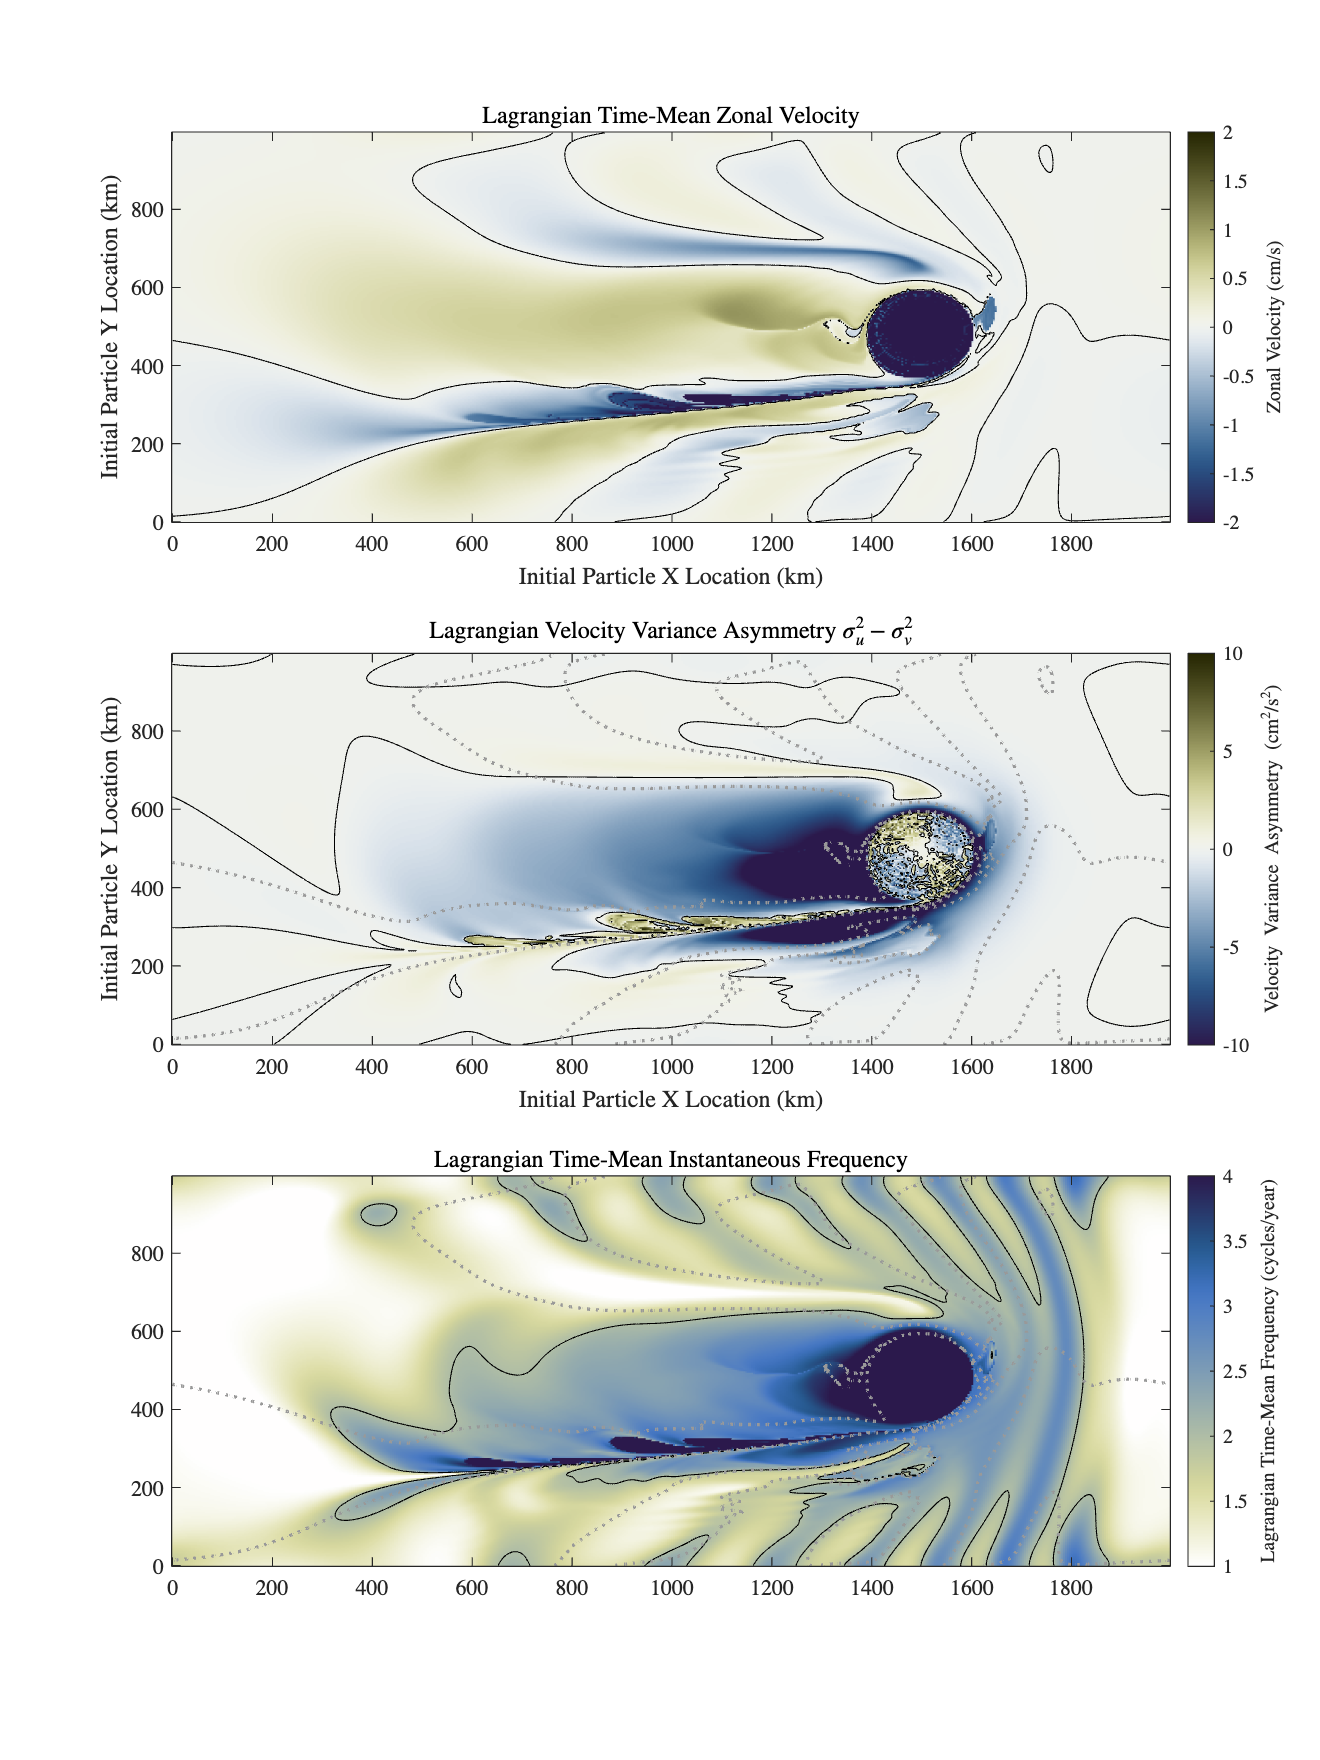

hf = figure();
hf.Position(3:4) = [1200,1600];
colormap(crameri('broc'))

tiledlayout(3,1)

nexttile;
jpcolor(x,y,mu'),axis tight,hold on
contour(x,y,mu',[0 0],'k')
hc=colorbar('location','EastOutside');
hc.Label.String = "Zonal Velocity (cm/s)";
title("Lagrangian Time-Mean Zonal Velocity")
xlabel('Initial Particle X Location (km)')
ylabel('Initial Particle Y Location (km)')
clim([-2 2])

nexttile;
jpcolor(x,y,(u_std.^2-v_std.^2)'),axis tight,hold on
contour(x,y,(u_std.^2-v_std.^2)',[0 0],'k')
contour(x,y,mu',[0 0],color=[1 1 1]*0.6,linewidth=1.5,linestyle=':')
hc=colorbar('location','EastOutside');
hc.Label.String = "Velocity Variance Asymmetry (cm^{2}/s^{2})";
title("Lagrangian Velocity Variance Asymmetry $\sigma_u^2-\sigma_v^2$")
xlabel('Initial Particle X Location (km)')
ylabel('Initial Particle Y Location (km)')
clim([-10 10])

ha=nexttile;
jpcolor(x,y,365*ombar'/2/pi),axis tight,hold on
contour(x,y,365*ombar'/2/pi,[2 2],'k')
contour(x,y,mu',[0 0],color=[1 1 1]*0.6,linewidth=1.5,linestyle=':')
hc=colorbar('location','EastOutside');
hc.Label.String = "Lagrangian Time-Mean Frequency (cycles/year)";
title("Lagrangian Time-Mean Instantaneous Frequency")
%xlabel('Time (days)')
%ylabel('Initial Particle Y Location (km)'),caxis([-1 1]/2)
colormap(ha,flipud(crameri('davos')))
clim([1 4])

This shows very clearly that the particles experiencing jet-like westward motion also experience variance that is enhanced in the zonal direction relative to the meridional direction (although it is not shown, it is both the case that zonal variance is enhanced and meridional variance is suppressed in that region), and finally with low-frequency motion.  

This identifies the westward jet as a characteristic feature of this eddy; therefore, we should account for its transport separately.  However, the fact that this feature occurs only near the top of the initial eddy suggests that it is associated with the initial condition.  It is not clear whether it should be counted as transport associated with the eddy (perhaps with the eddy's generation), or disregarded as an artifact of the initial condition. 

Note also that entrained fluid tends to exhibit high-frequency motion. 

Now let's create an index for the jet, and re-do our transport calculations. 

[xg,yg]=ndgrid(x,y); 
isInitiallyTrapped=reshape(isTrapped(1,:),length(x),length(y));
isAlwaysTrapped=reshape(mean(isTrapped,1)==1,length(x),length(y));
isEverTrapped=reshape(mean(isTrapped,1)~=0,length(x),length(y));
isInJet=vrep(vmean(mu,1),size(mu,1),1)<0&yg>yo(1)+R(1)&xg<xo(1)+R(1);

clear bool

bool{1}=isInitiallyTrapped&isAlwaysTrapped&~isInJet;%1159 0.88%%
bool{2}=isEverTrapped&~isAlwaysTrapped&~isInJet;%3445 2.6%
bool{3}=isInJet;%9130 6.97%
bool{4}=~isEverTrapped&~isInJet;%117338 89.5%

L=zeros(length(bool),1);
for i=1:length(bool)
    L(i)=length(find(bool{i}));
end

L./sum(L)*100;

meanu=zeros(size(drifter_u,1),length(bool));
meanv=zeros(size(drifter_v,1),length(bool));
for k=1:size(meanu,1)
    uk = drifter_u(k,:);
    vk = drifter_v(k,:);

    for i=1:length(bool)
         meanu(k,i)=mean(uk(vcolon(bool{i})));
         meanv(k,i)=mean(vk(vcolon(bool{i})));
    end
end

%find cumulative mean 
cummeanu=meanu;
cummeanv=meanv;
for k=1:size(meanu,1)
    cummeanu(k,:)=mean(meanu(1:k,:),1);
    cummeanv(k,:)=mean(meanv(1:k,:),1);
end

%now weight by area
weight=meanu;
for i=1:length(bool)
    weight(:,i) = length(find(bool{i}))/length(bool{1}(:)) + 0*weight(:,i);
end

%compute final positions
dx = x(2)-x(1);
xbins = x(1)-dx/2:dx:x(end)+dx/2;
ybins = y(1)-dx/2:dx:y(end)+dx/2;
xf = reshape(drifter_x(end,:),length(x),length(y));
yf = reshape(drifter_y(end,:),length(x),length(y));

for i=1:length(bool)
%need to revese x and yfor twodstats to give the right orientation
    [boolf{i},ymid,xmid] = twodstats(yf,xf,bool{i}+0,ybins,xbins);
end
%aresame(x,xmid),aresame(y,ymid)

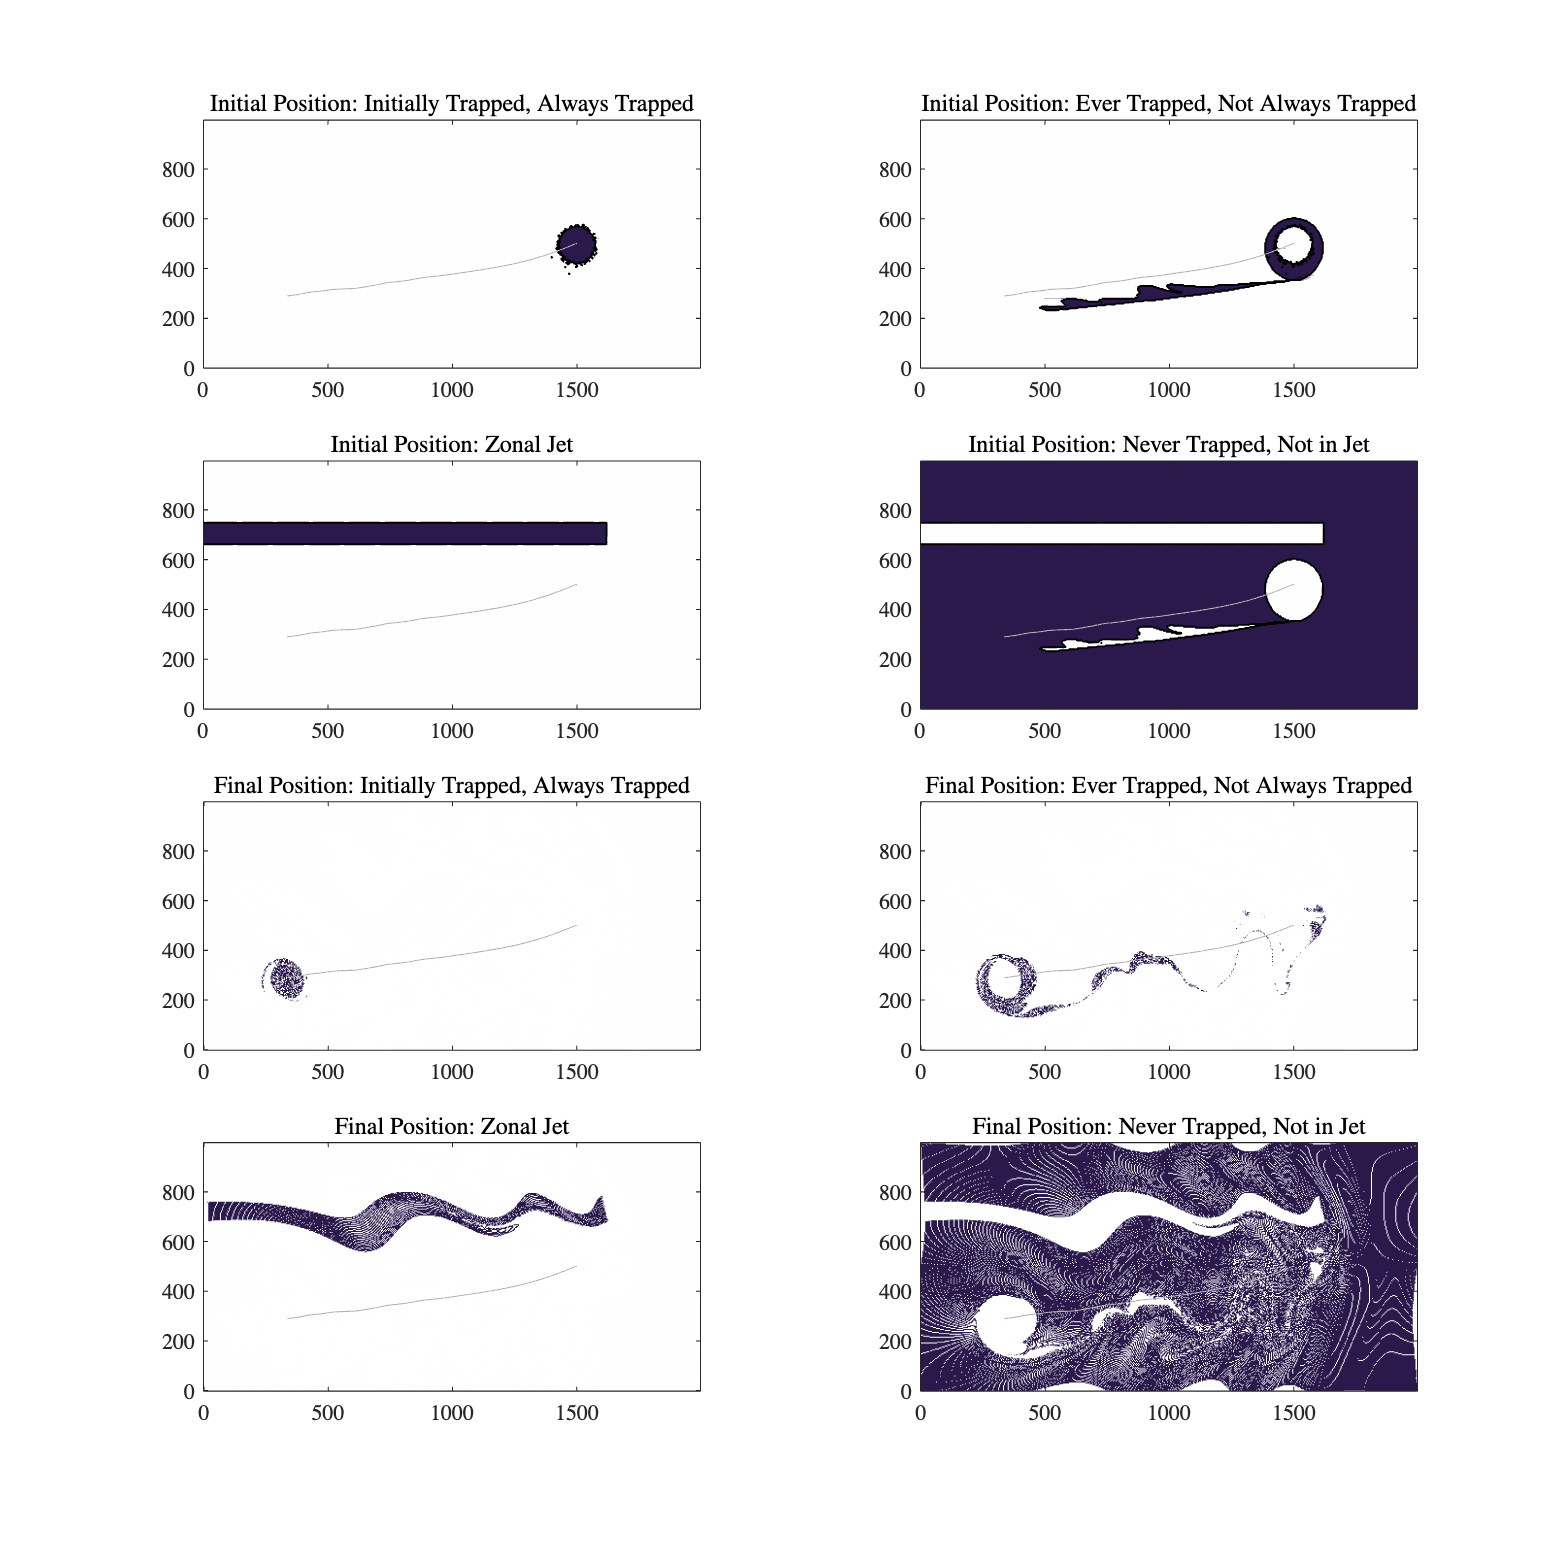

hf = figure();
hf.Position(3:4) = [1200,1200];
colormap(flipud(crameri('davos')))

tiledlayout(4,2);

nexttile
contourf(x,y,bool{1}');hold on, axis equal, axis tight,plot(xo,yo,color=[1 1 1]*0.7)
title("Initial Position: Initially Trapped, Always Trapped")

nexttile
contourf(x,y,bool{2}');hold on, axis equal, axis tight,plot(xo,yo,color=[1 1 1]*0.7)
title("Initial Position: Ever Trapped, Not Always Trapped")

nexttile
contourf(x,y,bool{3}');hold on, axis equal, axis tight,plot(xo,yo,color=[1 1 1]*0.7)
title("Initial Position: Zonal Jet")

nexttile
contourf(x,y,bool{4}');hold on, axis equal, axis tight,plot(xo,yo,color=[1 1 1]*0.7)
title("Initial Position: Never Trapped, Not in Jet")

nexttile
jpcolor(x,y,boolf{1}');hold on, axis equal, axis tight,plot(xo,yo,color=[1 1 1]*0.7)
title("Final Position: Initially Trapped, Always Trapped")

nexttile
jpcolor(x,y,boolf{2}');hold on, axis equal, axis tight,plot(xo,yo,color=[1 1 1]*0.7)
title("Final Position: Ever Trapped, Not Always Trapped")

nexttile
jpcolor(x,y,boolf{3}');hold on, axis equal, axis tight,plot(xo,yo,color=[1 1 1]*0.7)
title("Final Position: Zonal Jet")

nexttile
jpcolor(x,y,boolf{4}');hold on, axis equal, axis tight,plot(xo,yo,color=[1 1 1]*0.7)
title("Final Position: Never Trapped, Not in Jet")

dx = x(2)-x(1);%dx in km 
dA = dx.^2     %differential area in km^2, since dx=dy

dA = 15.2588

K = size(u,3); %number of time steps

%total area of fluid
max(x)*max(y)/1e6 %1.99 Mm^2

ans = 1.9883


%or if I attribute dA to each grid point
512*256*dA/1e6 %2 Mm^2

ans = 2

(max(x)+dx)*(max(y)+dx)/1e6 %2 Mm^2

ans = 2

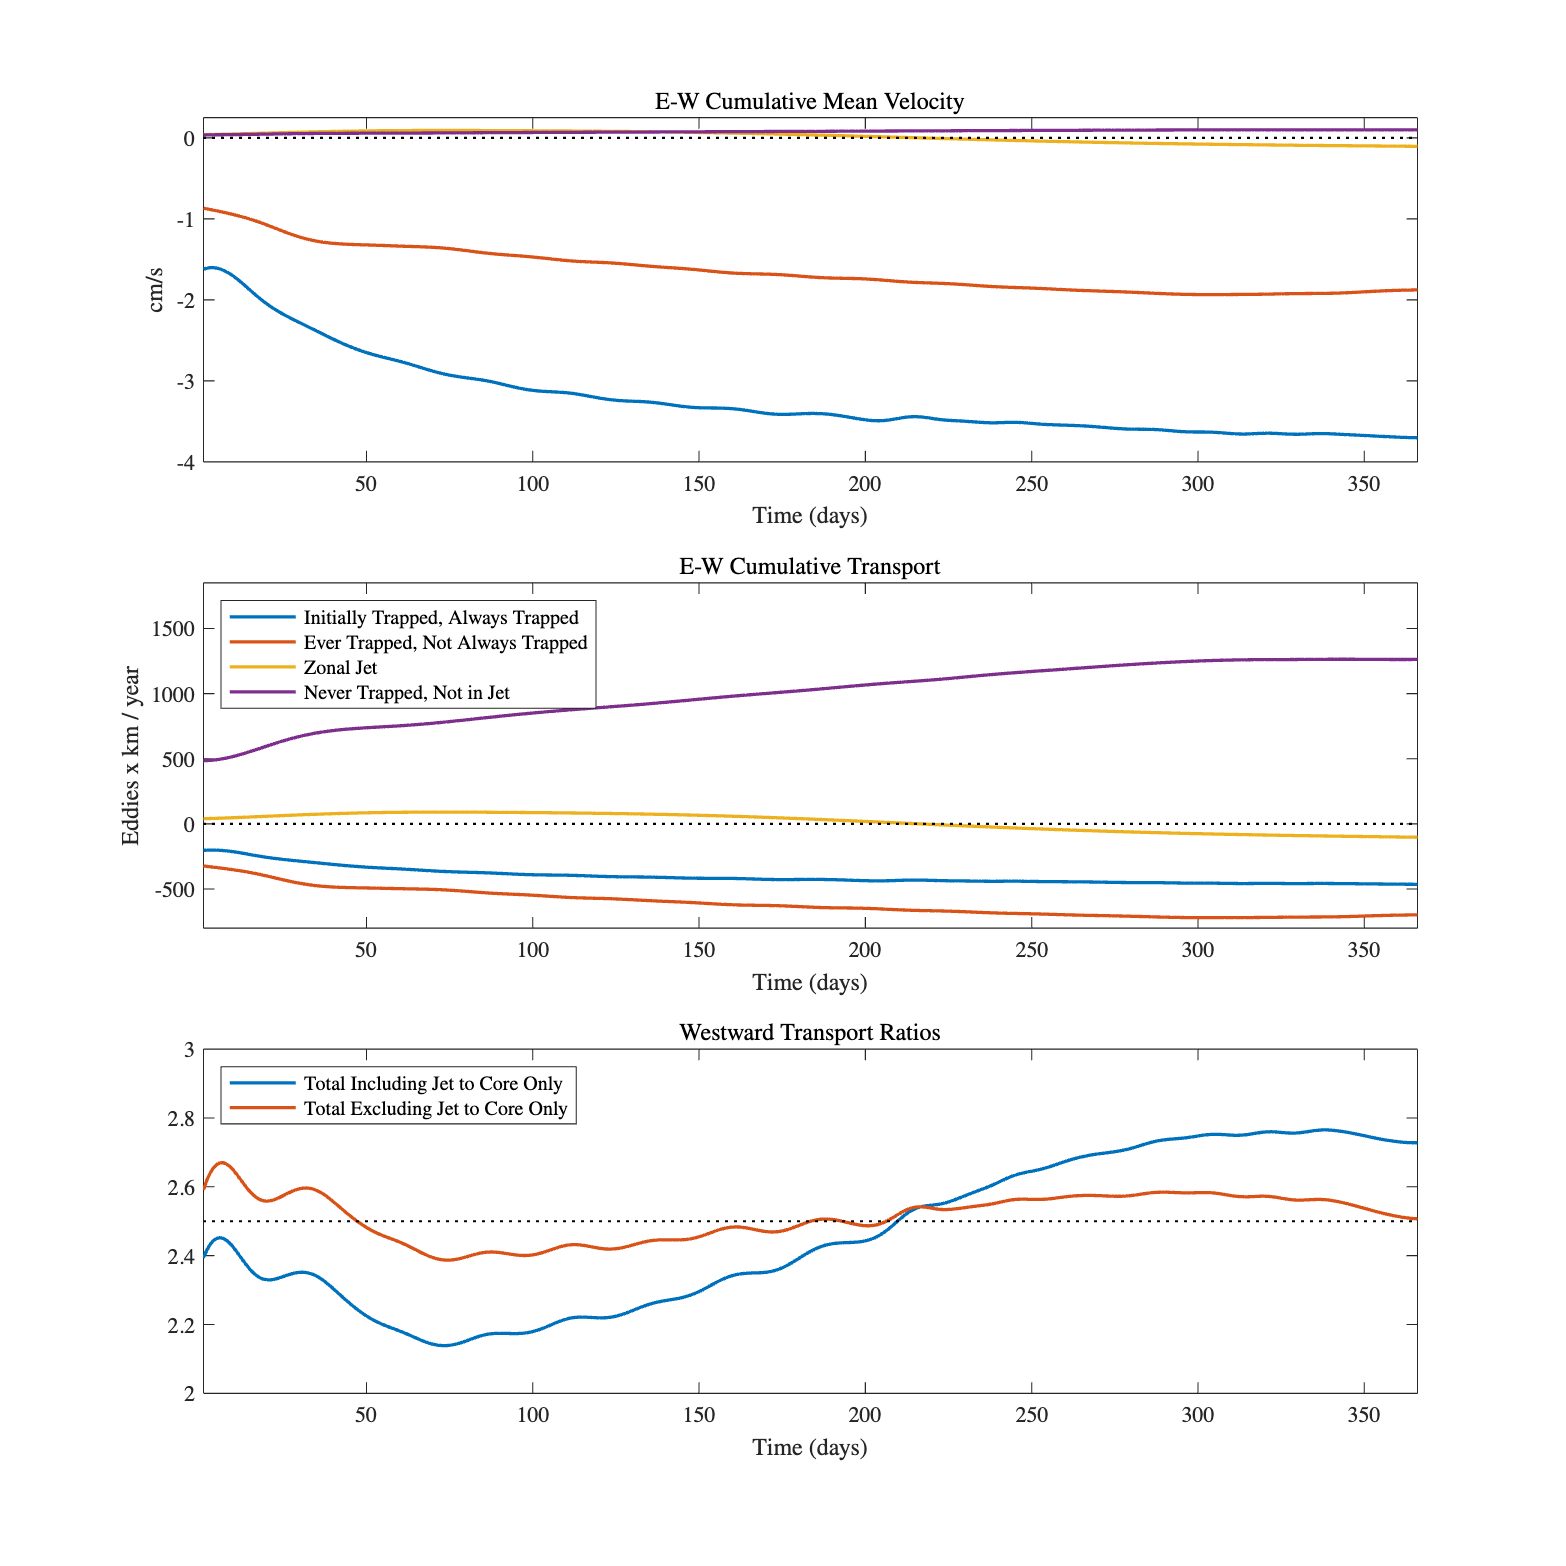


%initial and final areas of the eddy
[~,~,~,R]=curvemoments(xc,yc);
Eo = pi*R(1)^2;   %44564 km^2
Ef = pi*R(end)^2; %32505 km^2
% 

hf = figure();
hf.Position(3:4) = [1200,1200];

tiledlayout(3,1);

nexttile;
plot(cummeanu,linewidth=1.5);axis tight,hlines(0,'k:')
title('E-W Cumulative Mean Velocity')
ylabel('cm/s')
xlabel("Time (days)")
ylim([-4 0.25])

factor = 512*256*dA*(1/1000/100*24*3600*365)/Eo;

nexttile;
h=plot(weight.*cummeanu*factor,linewidth=1.5);axis tight,hlines(0,'k:'),hold on
%plot(weight(:,2).*cummeanu(:,2)*factor+weight(:,3).*cummeanu(:,3)*factor,linewidth=1.5);
title('E-W Cumulative Transport')
ylabel('Eddies x km / year')
xlabel("Time (days)")
ylim([-800 1850])

legend(h,'Initially Trapped, Always Trapped','Ever Trapped, Not Always Trapped',...
    'Zonal Jet','Never Trapped, Not in Jet','location','northwest')
nexttile;

ratio1 = 1 + (weight(:,2).*cummeanu(:,2) + weight(:,3).*cummeanu(:,3))./(weight(:,1).*cummeanu(:,1));
ratio2 = 1 + (weight(:,2).*cummeanu(:,2))./(weight(:,1).*cummeanu(:,1));
h=plot([ratio1 ratio2],linewidth=1.5);axis tight
hlines(2.5,'k:')
%title('Ratio of Total Transport, Excluding Jet, to Core-Only')
title('Westward Transport Ratios')
xlabel("Time (days)")
ylim([2 3])
legend(h,'Total Including Jet to Core Only','Total Excluding Jet to Core Only','location','northwest')

This shows that if we group the jet into the westward transport, we get a slightly (but not much) higher estimate of the transport bias, around 2.7 compared with 2.5 as in the previous LiveScript. 